# Meta Analysis of COVID-19 Patient Data 

Amiel Hundley, Owen Gift, Kasey Bryan 

BMES 543 

06/07/2022

%download GSE series from NCBI GEO website and save on computer
%also loads and returns data into Matlab
addpath ('c:\Users\hundl\Dropbox\bmes.ahmet');
addpath ('c:\Users\hundl\Dropbox\bmes.ahmet/qsb');
%https://www.ncbi.nlm.nih.gov/geo/query/acc.cgi?acc=GSE182279 (Data Set 1)
gse1=bmes_downloadandparsegse('GSE182279'); 

Reading C:\Users\hundl\AppData\Local\Temp\GSE182279.txt ...


%https://www.ncbi.nlm.nih.gov/geo/query/acc.cgi?acc=GSE164805 (Data Set 2)
gse2=bmes_downloadandparsegse('GSE164805');

Reading C:\Users\hundl\AppData\Local\Temp\GSE164805.txt ...


%https://www.ncbi.nlm.nih.gov/geo/query/acc.cgi?acc=GSE177477 (Data Set 3)
gse3=bmes_downloadandparsegse('GSE177477');

Reading C:\Users\hundl\AppData\Local\Temp\GSE177477.txt ...


%get(gse.Data) for each data set;
data1=gse1.Data;
data2=gse2.Data;
data3=gse3.Data;

%Download and parse gpl information
gpl1 = bmes_downloadandparsegpl('GPL30524');
gpl2 = bmes_downloadandparsegpl('GPL26963');
gpl3 = bmes_downloadandparsegpl('GPL23159');

gplprobes1 = gpl1.Data(:, strcmp(gpl1.ColumnNames, 'ID'));
gplgenes1 = gpl1.Data(:, strcmp(gpl1.ColumnNames, 'ORF'));
gseprobes1 = data1.rownames;
MAP_GSE_GPL1 = zeros(numel(gseprobes1),1);

gplprobes2 = gpl2.Data(:, strcmp(gpl2.ColumnNames, 'ID'));
gplgenes2 = gpl2.Data(:, strcmp(gpl2.ColumnNames, 'ORF'));
gseprobes2 = data2.rownames;
MAP_GSE_GPL2 = zeros(numel(gseprobes2),1);

gplprobes3 = gpl3.Data(:, strcmp(gpl3.ColumnNames, 'ID'));
gplgenes3 = gpl3.Data(:, strcmp(gpl3.ColumnNames, 'SPOT_ID'));
gplgenes3=gplgenes3(:,2);

%Spot ID descriptions for this data set have many details. 
% extract gene names from SPOT_ID description
for i=1:numel(gplgenes3)
    idx1=strfind(gplgenes3{i},'(');
    if ~isempty(idx1)
    idx1=idx1(1);
    idx2=strfind(gplgenes3{i},')');
    if ~isempty(idx2)
    idx2=idx2(1);
    if isempty(idx1) && isempty(idx2)
        gplgenes3{i}=gplgenes3{i};
    elseif ~isempty(idx1) && ~isempty(idx2)
    genestring=gplgenes3{i}((idx1+1):(idx2-1));
    gplgenes3{i}=genestring;
    end
    end
    end 
end

gseprobes3 = data3.rownames;
MAP_GSE_GPL3 = zeros(numel(gseprobes3),1);


% For each gseprobe, search gplprobes and use the corresponding
% gene. We will use a Map container to speed this up.
map1 = containers.Map(gplprobes1,1:numel(gplprobes1));
for i=1:numel(gseprobes1)
if map1.isKey(gseprobes1{i}); MAP_GSE_GPL1(i)=map1(gseprobes1{i}); end
end

map2 = containers.Map(gplprobes2,1:numel(gplprobes2));
for i=1:numel(gseprobes2)
if map2.isKey(gseprobes2{i}); MAP_GSE_GPL2(i)=map2(gseprobes2{i}); end
end

map3 = containers.Map(gplprobes3,1:numel(gplprobes3));
for i=1:numel(gseprobes3)
if map3.isKey(gseprobes3{i}); MAP_GSE_GPL3(i)=map3(gseprobes3{i}); end
end

gsegenes1 = gseprobes1; %make a copy, so entries not found will keep the probe name.
gsegenes1(find(MAP_GSE_GPL1)) = gplgenes1(MAP_GSE_GPL1(find(MAP_GSE_GPL1)));
%replace the DataMatrix object so it uses genes as rownames
data1= data1.rownames(':',gsegenes1);


gsegenes2 = gseprobes2; %make a copy, so entries not found will keep the probe name.
gsegenes2(find(MAP_GSE_GPL2)) = gplgenes2(MAP_GSE_GPL2(find(MAP_GSE_GPL2)));
%replace the DataMatrix object so it uses genes as rownames
data2= data2.rownames(':',gsegenes2);


gsegenes3 = gseprobes3; %make a copy, so entries not found will keep the probe name.
gsegenes3(find(MAP_GSE_GPL3)) = gplgenes3(MAP_GSE_GPL3(find(MAP_GSE_GPL3)));
%replace the DataMatrix object so it uses genes as rownames
data3= data3.rownames(':',gplgenes3(1:numel(data3.rownames)));

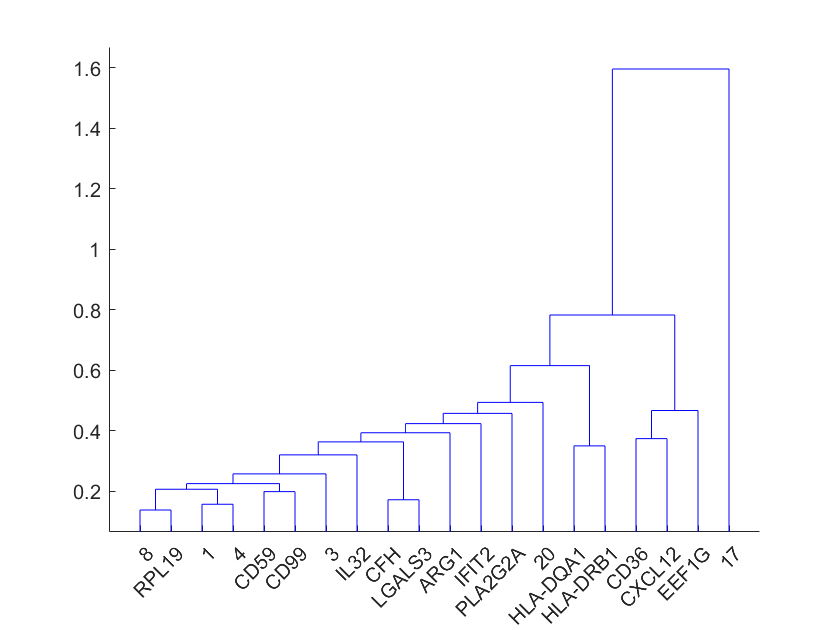

%Show a hierarchical clustering of samples.


%remove 90% of genes to show to try to only keep genes that vary most across samples
I=genevarfilter(data1, 'Percentile',90);
dataone=data1(I,:);

genedist1 = pdist(dataone,'spearman');
tree = linkage(genedist1,'average');
figure(1)
dendrogram(tree,20,'Labels',dataone.rownames)

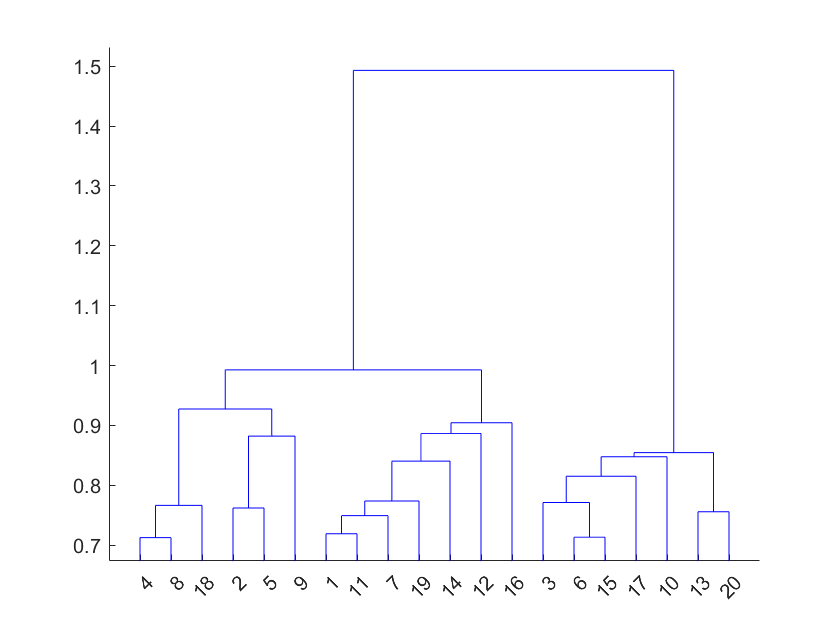

I2=genevarfilter(data2, 'Percentile',90);
datatwo=data2(I2,:);

genedist2 = pdist(datatwo,'spearman');
tree2 = linkage(genedist2,'average');
figure(2)
dendrogram(tree2,20,'Labels',datatwo.rownames)

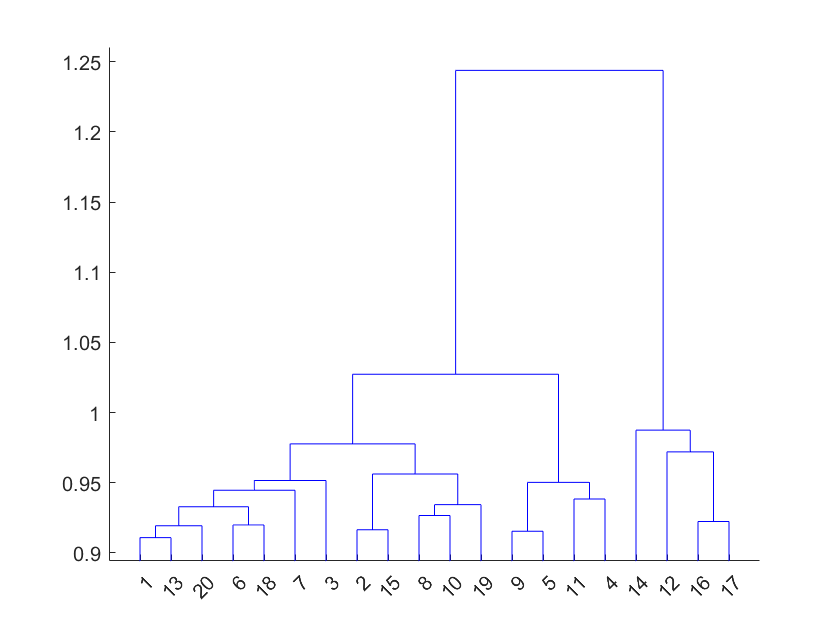


I3=genevarfilter(data3, 'Percentile',90);
datathree=data3(I3,:);

genedist3 = pdist(datathree,'spearman');
tree3 = linkage(genedist3,'average');
figure(3)
dendrogram(tree3,20,'Labels',datathree.rownames)

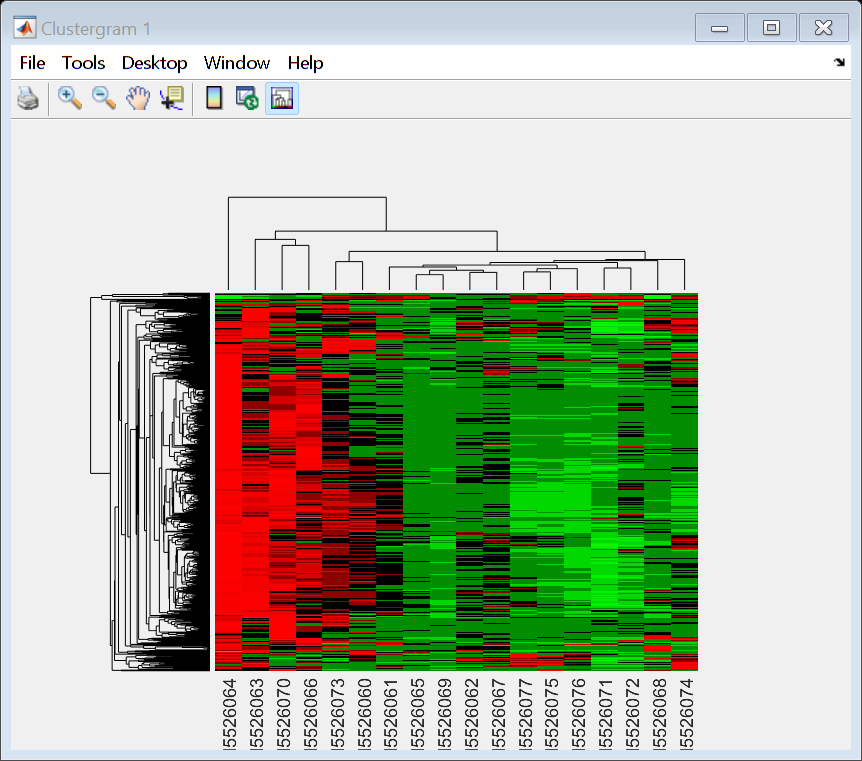

Clustergram object with 618 rows of nodes and 18 columns of nodes.



%Show a clustergram (heatmap) of expression
figure(4)
cg1 = clustergram(data1,'Standardize','Row')

%cg2 = clustergram(data2,'Standardize','Row')
%Matlab crashes when trying to compute this data set

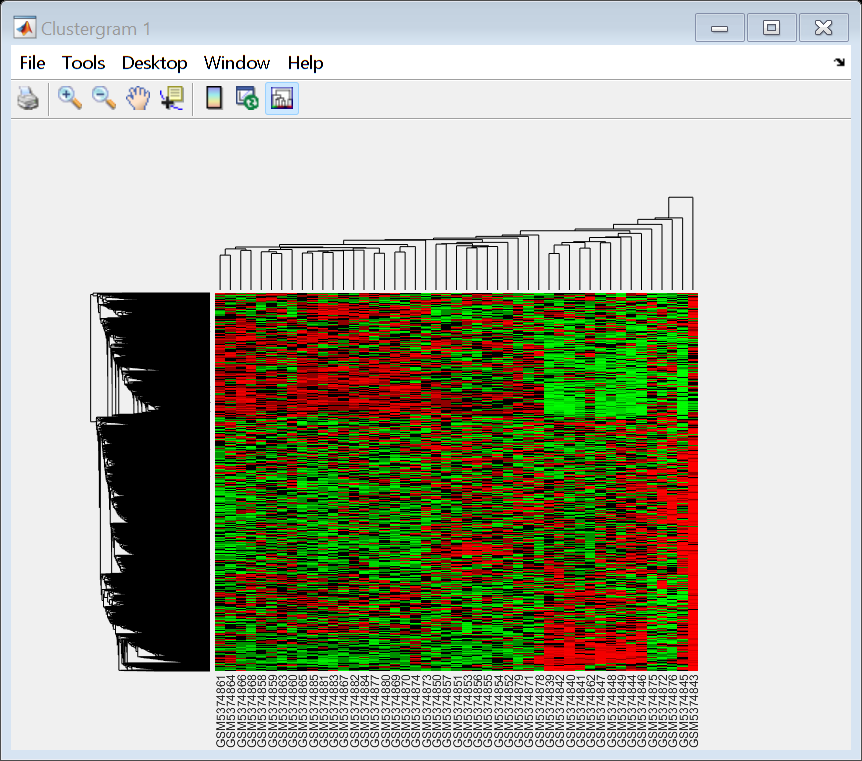

Clustergram object with 24351 rows of nodes and 47 columns of nodes.



figure(5)
cg3 = clustergram(data3,'Standardize','Row')


%Report the top 10 most different genes between the unhealthy samples and healthy control groups.
samplegroups1 = gse1.Header.Samples.characteristics_ch1(1,:);
samplesources1 = gse1.Header.Samples.source_name_ch1;
control1=strcmpi(samplegroups1,'disease: healthy control');
unhealthy1=strcmpi(samplegroups1,'disease: chilblain like lesion COVID 19');

% create a numerical vector to assign each sample to a group 1-2
Igroups1=zeros(1,numel(samplegroups1));
Igroups1(control1) = 1;
Igroups1(unhealthy1) = 2;
groupnames1={'Control' 'Unhealthy'};

%change the columnnames in the datamatrix.
colnames1=data1.colnames;
for i=1:2
    colnames1(Igroups1==i) = groupnames1(i); 
end
data1=data1.colnames(':',colnames1);

%Report the top 10 most different genes between the unhealthy and healthy control groups.
[~,pvals1]=ttest2(data1(:,control1)', data1(:, unhealthy1)');
fpvals1 = mafdr(pvals1);
[dpvals1]=mattest(data1(:,control1), data1(:, unhealthy1), 'permute',10);

log2fc = log2( mean(data1(:,control1),2) ./ mean(data1(:, unhealthy1),2) );
signedfc1 = 2.^log2fc;
signedfc1(signedfc1<1) = - 1./signedfc1(signedfc1<1);

%Add the foldchange information to the dpvals
dpvals1=[dpvals1 bioma.data.DataMatrix(signedfc1,'ColNames1',{'signedfc1'})];
I = dpvals1(:,'p-values')<=0.01 & abs(dpvals1(:,'signedfc1'))>=1.5;
dsigfc1 = dpvals1(I,:);
dsigfc1 = dsigfc1.sortrows('p-values');
fprintf('Found %d genes with pvalue<=0.01 and FC>=1.5 in Data Set 1. Showing top 10:\n',size(dsigfc1,1));

Found 196 genes with pvalue<=0.01 and FC>=1.5 in Data Set 1. Showing top 10:


disp(dsigfc1(1:10,:))

               p-values      signedfc1
    KLRD1       1.175e-05     -68.73  
    LTA        2.5877e-05    -9.7036  
    CCR2       9.5929e-05    -5.1227  
    CD28        9.792e-05    -10.002  
    CCL16      0.00011712     5.1084  
    IRAK1      0.00013472    -2.4051  
    TNFSF8     0.00014492    -9.7005  
    IL12RB1    0.00015386    -6.3383  
    BAX         0.0001556    -3.2693  
    CD4        0.00018092    -4.7979  



%Report the top 10 most different genes between the unhealthy samples and healthy control groups.
samplegroups2 = gse2.Header.Samples.characteristics_ch1(1,:);
samplesources2 = gse2.Header.Samples.source_name_ch1;
control2=strcmpi(samplesources2,'PBMC, HC');
unhealthy2=strcmpi(samplesources2,'PBMC, severe patient');

% create a numerical vector to assign each sample to a group 1-2
Igroups2=zeros(1,numel(samplegroups2));
Igroups2(control2) = 1;
Igroups2(unhealthy2) = 2;
groupnames2={'Control' 'Unhealthy'};

%change the columnnames in the datamatrix.
colnames2=data2.colnames;
for i=1:2
    colnames2(Igroups2==i) = groupnames2(i); 
end
data2=data2.colnames(':',colnames2);

%Report the top 10 most different genes between the unhealthy and healthy control groups.
[~,pvals2]=ttest2(data2(:,control2)', data2(:, unhealthy2)');
fpvals2 = mafdr(pvals2);
[dpvals2]=mattest(data2(:,control2), data2(:, unhealthy2), 'permute',10);

log2fc = log2( mean(data2(:,control2),2) ./ mean(data2(:, unhealthy2),2) );
signedfc2 = 2.^log2fc;
signedfc2(signedfc2<1) = - 1./signedfc2(signedfc2<1);

%Add the foldchange information to the dpvals
dpvals2=[dpvals2 bioma.data.DataMatrix(signedfc2,'ColNames2',{'signedfc2'})];
I = dpvals2(:,'p-values')<=0.01 & abs(dpvals2(:,'signedfc2'))>=1.5;
dsigfc2 = dpvals2(I,:);
dsigfc2 = dsigfc2.sortrows('p-values');
fprintf('Found %d genes with pvalue<=0.01 and FC>=1.5 in Data Set 2. Showing top 10:\n',size(dsigfc2,1));

Found 5403 genes with pvalue<=0.01 and FC>=1.5 in Data Set 2. Showing top 10:


disp(dsigfc2(1:10,:))

                  p-values      signedfc2
    MIR210HG      5.8218e-09    -1.6557  
    AC007298.1    2.2325e-08    -2.4697  
    AC009803.1    4.1421e-08    -1.7101  
    HLA-DOA       4.6695e-08     1.7797  
    AL161668.1    5.4521e-08     -1.615  
    LINC00626     6.4034e-08    -1.7476  
    SNHG11        6.6697e-08     1.6118  
    G016441       7.8068e-08     -1.785  
    TNNC2         8.0054e-08    -1.5024  
    G081590       9.6434e-08      -1.78  



%Report the top 10 most different genes between the unhealthy samples and healthy control groups.
samplegroups3 = gse3.Header.Samples.characteristics_ch1(1,:);
samplesources3 = gse3.Header.Samples.source_name_ch1;
control3=strcmpi(samplegroups3,'disease state: healthy control');
unhealthy3=strcmpi(samplegroups3,'disease state: SARS-CoV-2 positive');

% create a numerical vector to assign each sample to a group 1-2
Igroups3=zeros(1,numel(samplegroups3));
Igroups3(control3) = 1;
Igroups3(unhealthy3) = 2;
groupnames3={'Control' 'Unhealthy'};

%change the columnnames in the datamatrix.
colnames3=data3.colnames;
for i=1:2
    colnames3(Igroups3==i) = groupnames3(i); 
end
data3=data3.colnames(':',colnames3);

%Report the top 10 most different genes between the unhealthy and healthy control groups.
[~,pvals3]=ttest2(data3(:,control3)', data3(:, unhealthy3)');
fpvals3 = mafdr(pvals3);
[dpvals3]=mattest(data3(:,control3), data3(:, unhealthy3), 'permute',10);

log2fc = log2( mean(data3(:,control3),2) ./ mean(data3(:, unhealthy3),2) );
signedfc3 = 2.^log2fc;
signedfc3(signedfc3<1) = - 1./signedfc3(signedfc3<1);

%Add the foldchange information to the dpvals
dpvals3=[dpvals3 bioma.data.DataMatrix(signedfc3,'ColNames3',{'signedfc3'})];
I = dpvals3(:,'p-values')<=0.01 & abs(dpvals3(:,'signedfc3'))>=1.5;
dsigfc3 = dpvals3(I,:);
dsigfc3 = dsigfc3.sortrows('p-values');
fprintf('Found %d genes with pvalue<=0.01 and FC>=1.5 in Data Set 3. Showing top 10:\n',size(dsigfc3,1));

Found 4 genes with pvalue<=0.01 and FC>=1.5 in Data Set 3. Showing top 10:


disp(dsigfc3(:,:))

              p-values      signedfc3
    SIDT1     1.8508e-05    -1.6013  
    GPR22     2.0911e-05    -1.6817  
    ZNF41     2.8937e-05    -1.6175  
    DNAH17     0.0003897    -1.5872  



%Determine which genes are show common differential expression between
% data sets 1, 2, and 3 

a=dsigfc1.RowNames;
b=dsigfc2.RowNames;
c=dsigfc3.RowNames;

%similar differentially expressed genes between dataset1 and dataset2 
intersection1=intersect(a,b) %full list shown in dendrogram below

intersection1 = 19×1 cell array
    {'ARG1'     }
    {'ATG5'     }
    {'CD2'      }
    {'CD247'    }
    {'CD28'     }
    {'CLEC4E'   }
    {'ETS1'     }
    {'HAVCR2'   }
    {'HLA-DPA1' }
    {'HLA-DPB1' }
    {'HLA-DRA'  }
    {'ICAM3'    }
    {'NFATC2'   }
    {'NFATC3'   }
    {'PDGFRB'   }
    {'TCF4'     }
    {'TNFRSF10C'}
    {'ZAP70'    }
    {'ZEB1'     }


%similar differentially expressed genes between dataset1 and dataset3 
intersect(a,c)


ans =

  0×1 empty cell array





%similar differentially expressed genes between dataset2 and dataset3 
intersect(b,c)


ans =

  0×1 empty cell array



%Show a hierarchical clustering of similarly differentiated genes between
%dataset1 and dataset2
genedistinf = pdist(intersection1,'spearman');

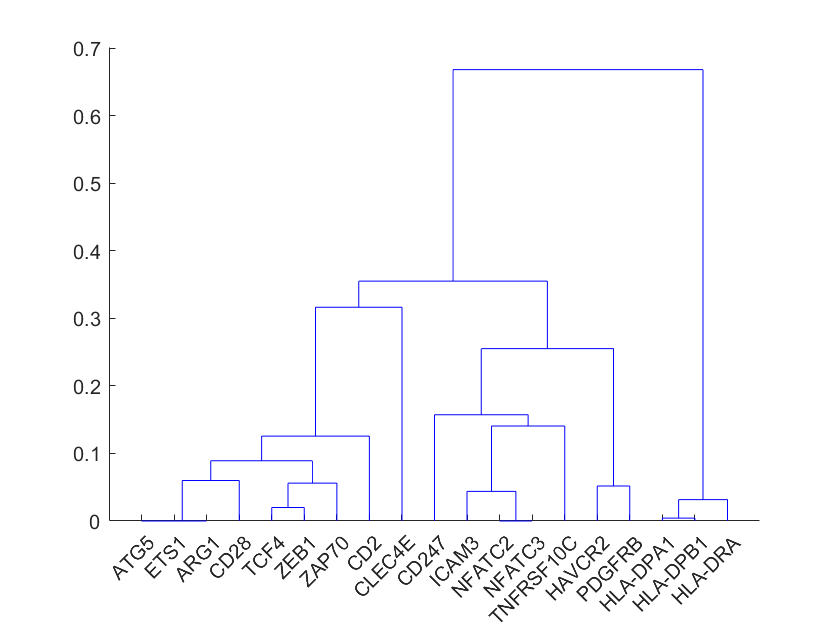

treeinf = linkage(genedistinf,'average');
figure(6)
dendrogram(treeinf,20,'Labels',intersection1)